라이브러리 다운로드

addpath(genpath('full/path/to/SaStatistics_and_Machine_Learning_Toolbox'))

#1

T=readtable('/MATLAB Drive/matlab 공모전/TTdata.csv');
f1 = T{:,'reye_ratio'}

f1 =     0.2775
    0.2775
    0.2775
    0.2775
    0.2630
    0.2891
    0.2775
    0.2936
    0.2775
    0.3084


f2 = T{:,'leye_ratio'}

f2 =     0.2911
    0.2936
    0.2911
    0.2936
    0.2911
    0.3049
    0.2775
    0.2936
    0.2951
    0.3039


f3 = T{:, 'eye_angle'}

f3 =    -0.9596
   -0.9742
   -0.9596
   -0.9742
   -0.9612
   -0.9769
   -0.9756
   -0.9727
   -0.9857
   -0.9920


f4 = T{:, 'nose_ratio'}

f4 =     0.4877
    0.4877
    0.4877
    0.4877
    0.4877
    0.5122
    0.4877
    0.4877
    0.4877
    0.4887


f5 = T{:, 'chin_sharp'}

f5 =    -0.3264
   -0.3264
   -0.3628
   -0.3246
   -0.3821
   -0.3773
   -0.3897
   -0.3246
   -0.3313
   -0.3518


tal = T{:, 'tal'}

tal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X= [f1,f2,f3,f4,f5]

X =     0.2775    0.2911   -0.9596    0.4877   -0.3264
    0.2775    0.2936   -0.9742    0.4877   -0.3264
    0.2775    0.2911   -0.9596    0.4877   -0.3628
    0.2775    0.2936   -0.9742    0.4877   -0.3246
    0.2630    0.2911   -0.9612    0.4877   -0.3821
    0.2891    0.3049   -0.9769    0.5122   -0.3773
    0.2775    0.2775   -0.9756    0.4877   -0.3897
    0.2936    0.2936   -0.9727    0.4877   -0.3246
    0.2775    0.2951   -0.9857    0.4877   -0.3313
    0.3084    0.3039   -0.9920    0.4887   -0.3518


y= tal

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


save('TTdata.mat','X','y')

데이터 스플릿

%training set, 0% validation set and 30% test set.
[train_idx, ~, test_idx] = dividerand(14630, 0.8,0.0,0.2);
x_train = X(train_idx, :);
y_train = y(train_idx);
x_test = X(test_idx, :);
y_test = y(test_idx);

`Define the parameter grid`

param_grid = struct('n_estimators', [100, 200, 300, 500], ...
                    'max_features', {'sqrt'}, ...
                    'min_samples_leaf', 1, ...
                    'min_samples_split', 2, ...
                    'max_depth', [5, 10, 50, 100, NaN], ...
                    'criterion', {'gini'});

`랜덤 포레스트 분류기에 사용할 트리의 개수 정의`

% 랜덤 포레스트 분류기에 사용할 트리의 개수를 정의합니다.
nTrees = 100;

`TreeBagger를 사용하여 랜덤 포레스트 분류기 객체를 만듭니다.`

rf0_tal = TreeBagger(nTrees, x_train, y_train, 'Method', 'classification', 'NumPredictorsToSample', 'all', 'OOBPrediction', 'on');

예측 수행 및 예측 결과를 숫자로 변환

% 테스트 세트를 사용하여 예측을 수행합니다.
y_best_rf = predict(rf0_tal, x_test);

% 문자열 형태의 예측 결과를 숫자로 변환합니다.
y_best_rf = str2double(y_best_rf);

정확도 계산

% 정확도를 계산하여 출력합니다.
accuracy = sum(y_test == y_best_rf) / numel(y_test);
disp(['정확도:', num2str(accuracy)]);

정확도:0.85543


시각화

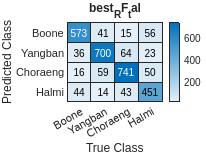

% 혼동 행렬(Confusion matrix)을 생성
cf_matrix_rf0_2 = confusionmat(y_best_rf, y_test);
classNames = {'Boone', 'Yangban', 'Choraeng', 'Halmi'};
numClasses = length(classNames);


% 혼동 행렬 시각화
figure;
heatmap(classNames, classNames, cf_matrix_rf0_2);
title('best_RF_tal');
xlabel('True Class');
ylabel('Predicted Class');